# Periodic State Space manipulation

The toolBox defines the PhasorSS class, that uses PhasorArray to define Linear Periodic State space systemes. 

Two type of system can be defined using theses object : 

- T is fixed: 

                                 
$$\dot{x} = A(t) x + B(t) u 
\\
y = C(t) x + D(t) u 
\\
A(t) = \sum_{k=-m} ^{k=m}A_k e^{jk\frac{2\pi}{T}t} \quad  \text{idem B(t), C(t), D(t)}$$


- Varying frequency :

                                 
$$\dot{x} = A(\theta) x + B(\theta) u 
\\
y = C(\theta) x + D(\theta) u 
\\
A(\theta) = \sum_{k=-m} ^{k=m}A_k e^{jk\theta} \quad  \text{idem B(\theta), C(\theta), D(\theta)}
\\
\theta = p(t,x,u)$$


In both case the decomposition of state matrix is considered time invariant and described through their respective phasorArray

The usual function (step, lsim, intial...) are defined. 

Additionnaly, to simulate a periodic input defined by a phasor array U, stepu is defined. 

Similarly to classic ss, phasorSS supports 2D indexing to extract specific output/input sets. 

## Basic exemple

T= 0.1; %s
nx = 3;
nu = 2 ;
ny = 2;
A = PhasorArray.randomPhasorArrayWithPole(3,[-15 -10 -5],T,'h',10).reduce(10)

A = 3x3x21 PhasorArray of double representing a 3x3 real-valued periodic matrix with 10 harmonics

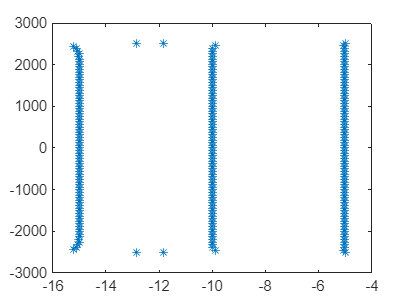

figure
plot(A.HmqNEig(40,T),'*')

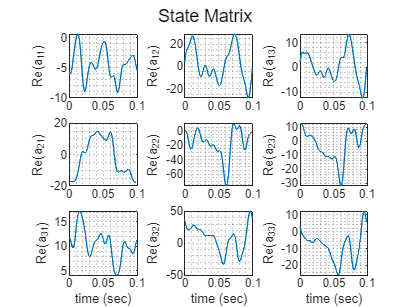

figure        
plot(A,T,title='State Matrix')


B = PhasorArray.random(nx,nu,5);
C = PhasorArray.random(ny,nx,5);

G = PhasorSS(A,B,C,[],T,"InputName",{'U','W'},'OutputName',{"Y","z"})

G = PhasorSS object with properties: 

             A: [3×3×21 PhasorArray]
             B: [3×2×11 PhasorArray]
             C: [2×3×11 PhasorArray]
             D: [2×2 PhasorArray]
     StateName: {'x1'  'x2'  'x3'}
     InputName: {'U'  'W'}
    OutputName: {'Y'  'z'}
             T: 0.1000

Continuous time Linear Time-Varying State-Space model with 3 states, 2 inputs, 2 outputs and period T=0.1
 See all properties

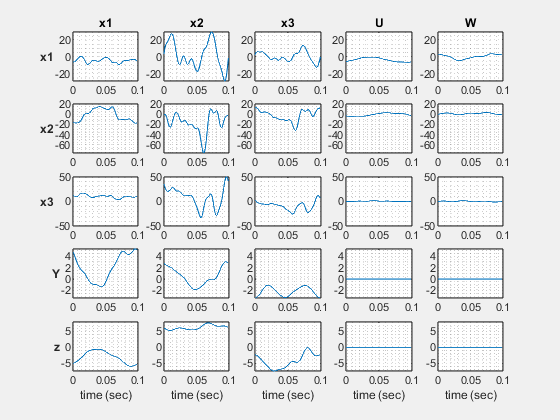

figure
G.plot()

## Simulation

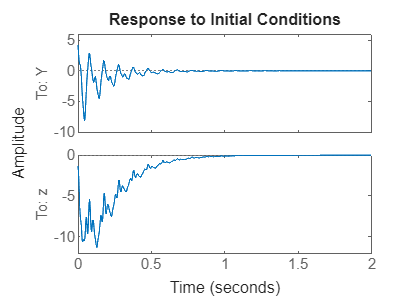

Real valued LTP ss


figure
initial(G,ones(3,1),20*T)


figure
step(G,20*T)

Real valued LTP ss


Error using DynamicSystem/step (line 97)
Unable to perform assignment because the size of the left side is 2-by-2 and the size of the right side is 2-by-1.

Error in PhasorSS/step (line 1101)
                    step(sysltv,t,stepOpt);


%periodic input for W and U 
UW = PhasorArray.random(2,1,5)
figure
plot(UW)
figure
stepu(G,20*T,UW)

t = 0:T/100:20*T-T/100;
uw = [t*25-70;atan((t-4*T)/0.3)*30];
figure
plot(t,uw)
figure
lsim(G,t,uw,ones(3,1))

figure
impulse(G,20*T)

